This file contains the results of inductive and resistive noise in a 3x3 NoC, broken out by routers 0, 1, 3, and 4.

## Resistive

This is for resistive noise <= 5.

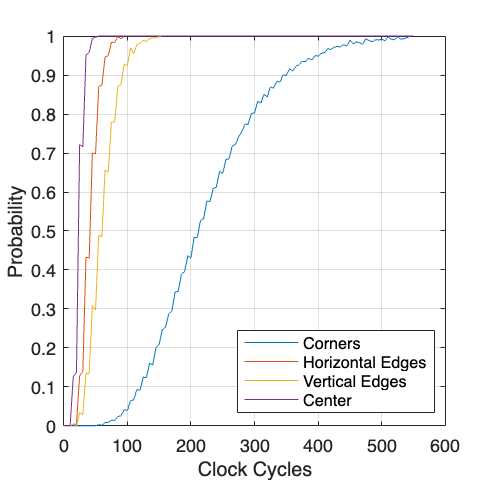

data = readmatrix('Data/Jonah/Individual/Resistive_5/r0.csv');
r0_x=data(1:2:end);
r0_y=data(2:2:end);

data = readmatrix('Data/Jonah/Individual/Resistive_5/r1.csv');
r1_x=data(1:2:end);
r1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Individual/Resistive_5/r3.csv');
r3_x=data(1:2:end);
r3_y=data(2:2:end);

data = readmatrix('Data/Jonah/Individual/Resistive_5/r4.csv');
r4_x=data(1:2:end);
r4_y=data(2:2:end);

fig_0 = figure("Units","inches","Position",[3,3,3.8,3.7]);

plot(r0_x,r0_y, ...
     r1_x,r1_y, ...
     r3_x,r3_y, ...
     r4_x,r4_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
legend("Corners","Horizontal Edges","Vertical Edges","Center","Location","southeast");
exportgraphics(fig_0, "VMCAI_25/3x3_resistive_final.png", "Resolution",300);

## Inductive

This is for inductive noise less <= 1

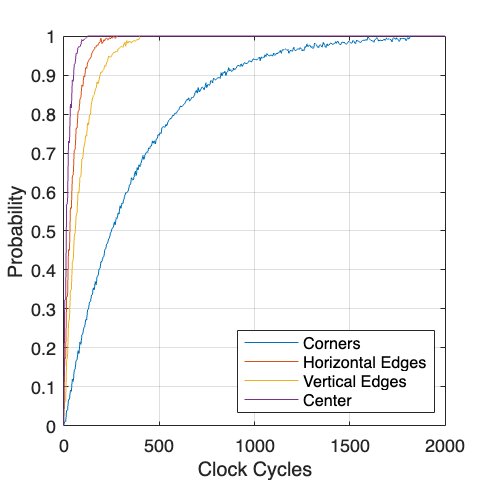

data = readmatrix('Data/Jonah/Individual/Inductive_1/r0.csv');
r0_x=data(1:2:end);
r0_y=data(2:2:end);

data = readmatrix('Data/Jonah/Individual/Inductive_1/r1.csv');
r1_x=data(1:2:end);
r1_y=data(2:2:end);

data = readmatrix('Data/Jonah/Individual/Inductive_1/r3.csv');
r3_x=data(1:2:end);
r3_y=data(2:2:end);

data = readmatrix('Data/Jonah/Individual/Inductive_1/r4.csv');
r4_x=data(1:2:end);
r4_y=data(2:2:end);

fig_1 = figure("Units","inches","Position",[3,3,3.8,3.7]);

plot(r0_x,r0_y, ...
     r1_x,r1_y, ...
     r3_x,r3_y, ...
     r4_x,r4_y);
grid on;
xlabel("Clock Cycles");
ylabel("Probability");
legend("Corners","Horizontal Edges","Vertical Edges","Center","Location","southeast");
exportgraphics(fig_1, "VMCAI_25/3x3_inductive_final.png", "Resolution",300);